%% ex1_glycolysis_selkov_hopf.m
% Selkov glycolysis model:
%   x' = -x + a y + x^2 y
%   y' =  b - a y - x^2 y
%
% Equilibrium: (x*,y*) = (b, b/(a+b^2))
% Hopf curve (trace=0): letting s = a + b^2,
%   s^2 + s - 2 b^2 = 0  =>  s = (-1 + sqrt(1+8 b^2))/2
%   a_c(b) = s - b^2
%
% We fix b and vary a across a_c. Define dimensionless distance:
%   mu = (a - a_c)/a_c
%
% Demonstrations:
%   1) Phase portrait with nullclines and trajectory (for a chosen mu)
%   2) Sweep a and estimate limit-cycle amplitude/period vs mu

clear; close all; clc;

%% Parameters
b = 0.5;

% Hopf threshold a_c for this b
s = (-1 + sqrt(1 + 8*b^2))/2;
a_c = s - b^2;
fprintf('Selkov model: b = %.3f, Hopf a_c = %.6f\n', b, a_c);

Selkov model: b = 0.500, Hopf a_c = 0.116025


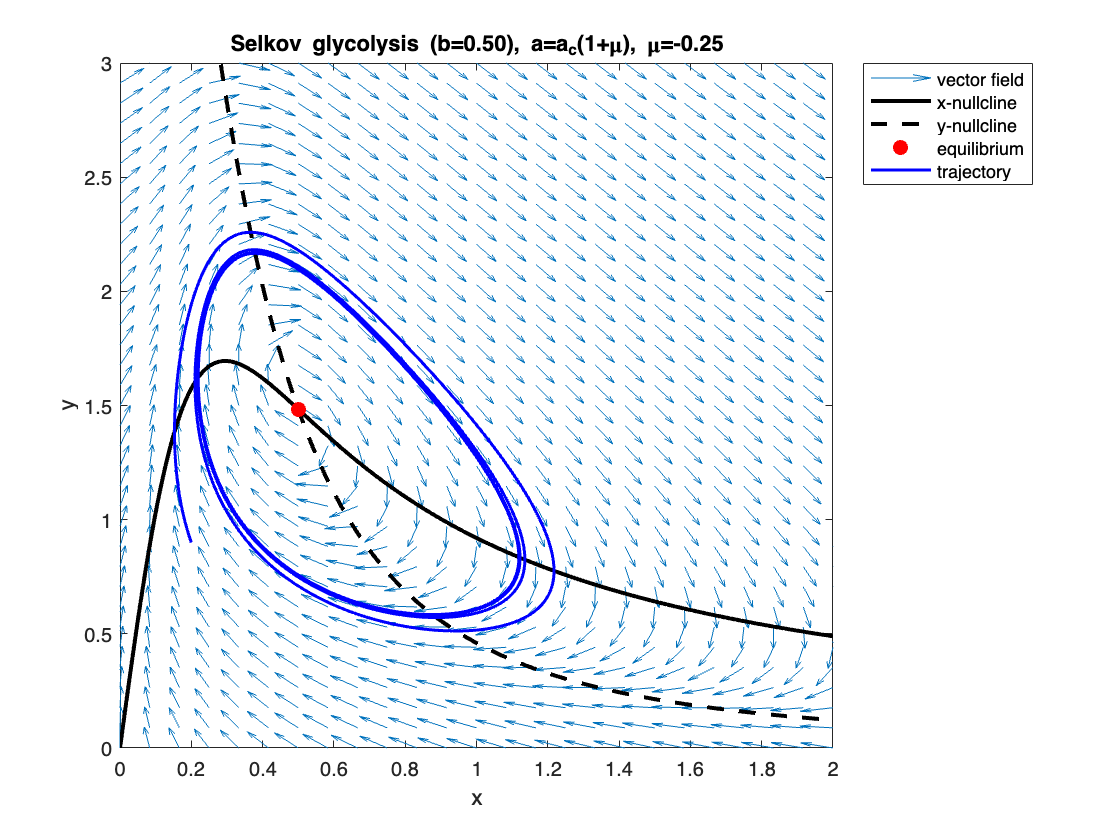


% Dimensionless distances around Hopf
mu_list = linspace(-0.6, 1.0, 17);
a_list  = a_c*(1 + mu_list);

%% Choose one parameter for phase portrait
mu_show = -0.25;                  % try also negative to show equilibrium regime
a_show  = a_c*(1 + mu_show);

%% Vector field + nullclines + a trajectory
figure('Name','Selkov: phase portrait'); hold on; box on;

% Grid for vector field
xg = linspace(0, 2.0, 25);
yg = linspace(0, 3.0, 35);
[X,Y] = meshgrid(xg, yg);
[dX, dY] = selkov_rhs(0, X, Y, a_show, b);

% Normalize arrows for readability (avoid huge arrows)
[U,V] = normalize_quiver(dX, dY);
quiver(X, Y, U, V, 0.8);

% Nullclines (analytic)
% x-nullcline: -x + a y + x^2 y = 0 => y = x/(a + x^2)
% y-nullcline:  b - a y - x^2 y = 0 => y = b/(a + x^2)
xx = linspace(0, 2.0, 800);
y_xnull = xx ./ (a_show + xx.^2);
y_ynull = b  ./ (a_show + xx.^2);
plot(xx, y_xnull, 'k-',  'LineWidth', 2);
plot(xx, y_ynull, 'k--', 'LineWidth', 2);

% Equilibrium
xstar = b;
ystar = b/(a_show + b^2);
plot(xstar, ystar, 'ro', 'MarkerFaceColor','r', 'MarkerSize', 7);

% Trajectory simulation
x0 = 0.2; y0 = 0.9;
tspan = [0 400];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.5);
[t,XYtraj] = ode45(@(t,z) selkov_ode(t,z,a_show,b), tspan, [x0;y0], opts);
plot(XYtraj(:,1), XYtraj(:,2), 'b-', 'LineWidth', 1.5);

xlabel('x'); ylabel('y');xlim([min(xg),max(xg)]);ylim([min(yg),max(yg)])
title(sprintf('Selkov glycolysis (b=%.2f), a=a_c(1+\\mu), \\mu=%.2f', b, mu_show));
legend({'vector field','x-nullcline','y-nullcline','equilibrium','trajectory'}, ...
       'Location','northeastoutside');

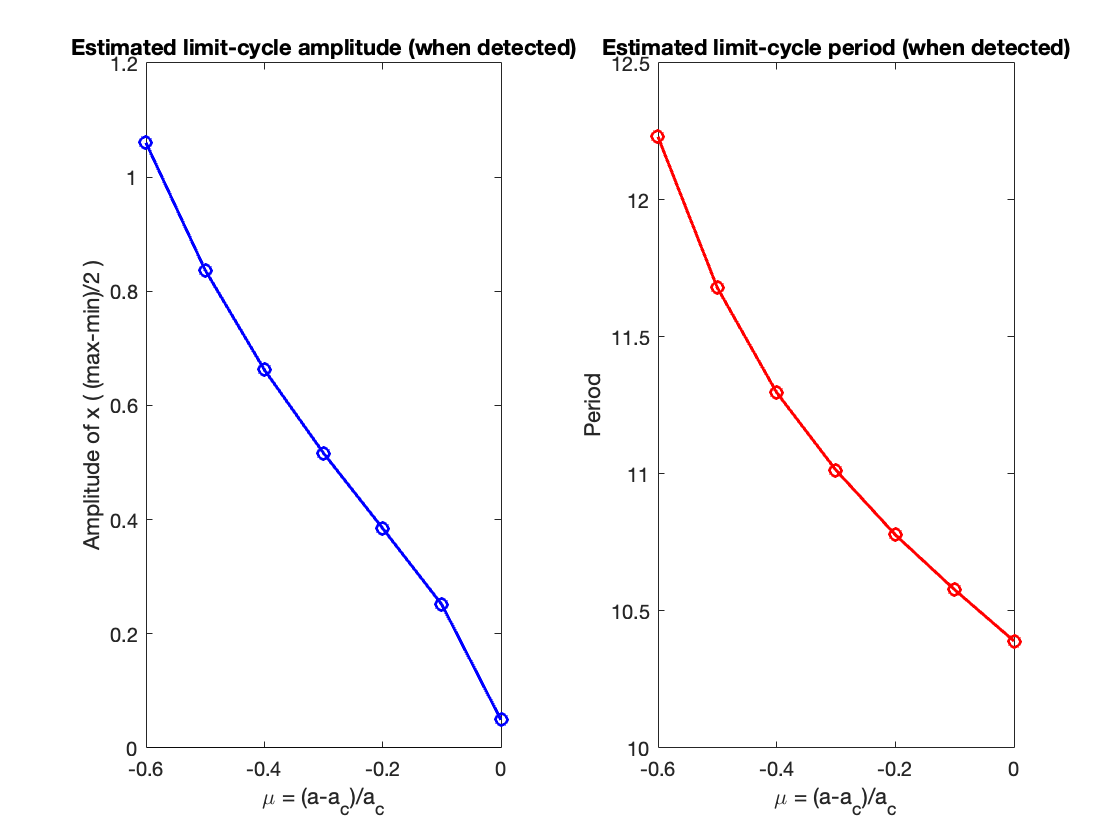


%% Limit-cycle amplitude/period vs mu sweep
amp = nan(size(mu_list));
per = nan(size(mu_list));
isCycle = false(size(mu_list));

% Initial condition for sweep (same for all)
z0 = [0.2; 0.9];

for k = 1:numel(a_list)
    a = a_list(k);

    % integrate long enough to settle
    tspan = [0 600];
    [t,z] = ode45(@(t,zz) selkov_ode(t,zz,a,b), tspan, z0, opts);

    x = z(:,1);
    % Decide whether it is oscillating: use amplitude on the last 30% window
    [amp_k, per_k] = estimate_cycle_metrics(t, x, 0.7);

    % Heuristic threshold: if amp is "clearly nonzero" and period is finite
    if ~isnan(amp_k) && amp_k > 1e-2 && ~isnan(per_k)
        isCycle(k) = true;
        amp(k) = amp_k;
        per(k) = per_k;
    else
        isCycle(k) = false;
    end
end

figure('Name','Selkov: amplitude/period vs mu'); tiledlayout(1,2);

nexttile; hold on; box on;
plot(mu_list(isCycle), amp(isCycle), 'bo-', 'LineWidth', 1.5);
yline(0,'k-');
xlabel('\mu = (a-a_c)/a_c'); ylabel('Amplitude of x ( (max-min)/2 )');
title('Estimated limit-cycle amplitude (when detected)');

nexttile; hold on; box on;
plot(mu_list(isCycle), per(isCycle), 'ro-', 'LineWidth', 1.5);
xlabel('\mu = (a-a_c)/a_c'); ylabel('Period');
title('Estimated limit-cycle period (when detected)');


%% ---- Local functions (MATLAB allows local functions at end of script) ----

function dz = selkov_ode(~, z, a, b)
    x = z(1); y = z(2);
    dx = -x + a*y + x^2*y;
    dy =  b - a*y - x^2*y;
    dz = [dx; dy];
end

function [dx,dy] = selkov_rhs(~, x, y, a, b)
    dx = -x + a*y + x.^2.*y;
    dy =  b - a*y - x.^2.*y;
end

function [U,V] = normalize_quiver(Uraw, Vraw)
    S = sqrt(Uraw.^2 + Vraw.^2);
    S(S==0) = 1;
    U = Uraw ./ S;
    V = Vraw ./ S;
end

function [amp, per] = estimate_cycle_metrics(t, x, transientFrac)
    % Estimate amplitude and period from time-series x(t).
    % transientFrac = fraction of trajectory treated as transient (e.g. 0.7 keeps last 30%).
    %
    % amplitude = (max - min)/2 on last window.
    % period: average spacing of local maxima on last window.
    n = numel(t);
    i0 = max(1, floor(transientFrac*n));
    tt = t(i0:end);
    xx = x(i0:end);

    amp = 0.5*(max(xx) - min(xx));

    % find local maxima (no toolbox)
    idx = find(xx(2:end-1) > xx(1:end-2) & xx(2:end-1) > xx(3:end)) + 1;
    if numel(idx) < 4
        per = NaN;
        return;
    end

    % use last few peaks
    idx = idx(max(1,end-5):end);
    per = mean(diff(tt(idx)));
end
